# Binary Classification using perception neural network model

% List the sample points in the coordinate system
sample_points =   [-9,  1, -12, -4,  0, 5;     % x-coordinate
                   15, -8,   4,  5, 11, 9];    % y-coordinate
category_labels = [ 0, 1,   0,  0,  0, 1];    % expectated output

% Plot these sample points
scatter([-9, -12, -4, 0], [15, 4, 5, 11], 'r*');
hold on;
scatter([1, 5], [-8, 9], 'b^');
hold off;
grid on;
axis([-14, 8, -10, 16]);
xlabel('x');
ylabel('y');
legend('class 0', 'class 1');

Now we want to find a line to separate the 2 classes:

learning_rate = 0.01;

Input = [ones(1, 6); sample_points]

Input =      1     1     1     1     1     1
    -9     1   -12    -4     0     5
    15    -8     4     5    11     9


# Step 0:  Initialization

Assume the weights and bias to be assigned to 0.         $\vec{W} =\text{ }\left\lbrack \begin{array}{c}
b\\
w_1 \\
w_2 
\end{array}\right\rbrack =\text{ }\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$

Weights = [0
           0
           0]';  

# Step 1:  Iteration 1st

Calculate the output :  $v=\vec{W} P=\text{ }{\left\lbrack \begin{array}{c}
b\\
w_1 \\
w_2 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
1\\
x\\
y
\end{array}\right\rbrack$  and  $Output=hardlim\left(v\right)=hardlim\left({\left\lbrack \begin{array}{c}
b\\
w_1 \\
w_2 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
1\\
x\\
y
\end{array}\right\rbrack \right)=\text{ }\left\lbrace \begin{array}{c}
1 & v\text{ }\ge 0\\
0 & v<0
\end{array}\right.$

v = Weights * Input;
Output = hardlim(v)   % Calculate the output of perceptionnetwork in 1st iteration

Output =      1     1     1     1     1     1


According to the error (Expectation - Output) to adjust the weights and bias.   

% Calculate the error :
error = mae(category_labels - Output)

error =    0.666666666666667


% Adjust the weights
Weights = Weights + learning_rate * (category_labels - Output) * Input';

# Step 2: Iteration 2nd

v = Weights * Input;
Output = hardlim(v)

Output =      0     1     0     0     0     0


error = mae(category_labels - Output)

error =    0.166666666666667


% Adjust the weights once again
Weights = Weights + learning_rate * (category_labels - Output) * Input';

# Step 3 : Iteration 3rd

v = Weights * Input;
Output = hardlim(v)

Output =      0     1     0     0     0     0


error = mae(category_labels - Output)

error =    0.166666666666667


Weights = Weights + learning_rate * (category_labels - Output) * Input';

# Step 4 : Iteration 4th

v = Weights * Input;
Output = hardlim(v)

Output =      0     1     0     0     0     1


error = mae(category_labels - Output)

error =      0


# After 4 iterations, the mean absolute error reached to 0. 

# Algorithm has converged.  Iterations end.

## The actual output meets up to the expectation.

Weights = Weights + learning_rate * (category_labels - Output) * Input'

Weights =   -0.020000000000000   0.350000000000000  -0.170000000000000


## Plot the separator line  ${\left\lbrack \begin{array}{c}
b\\
w_1 \\
w_2 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
1\\
x\\
y
\end{array}\right\rbrack =0$

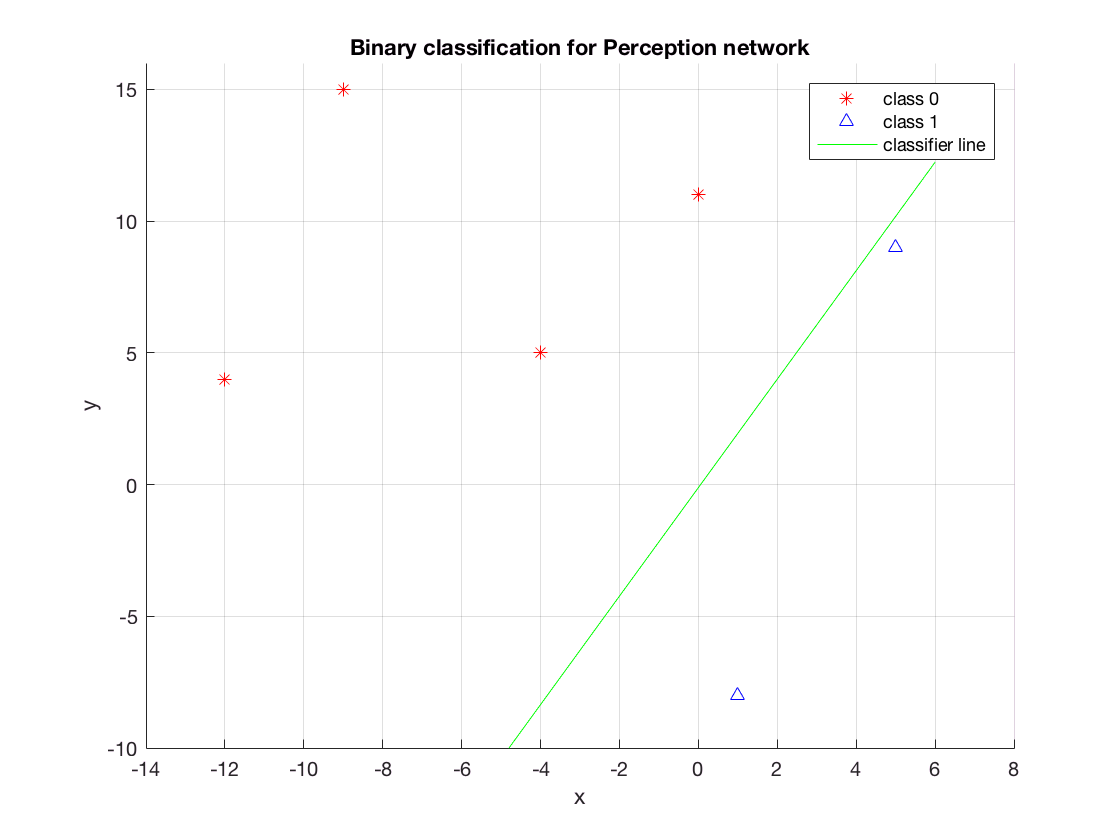

x = -12:1:6;
y = (-Weights(1, 1) - Weights(1, 2)*x)/Weights(1, 3);
hold on;
plot(x, y, 'g-');
title('Binary classification for Perception network');
legend('class 0', 'class 1', 'classifier line');

%%  perception_classifier;